# Explicit Runge-Kutta Methods

#### Example 2.2

Derive two second-order Runge-Kutta ERK methods where 

(i)     $c_2 = 1$;

% Define symbolic variables
syms a21 b1 b2 c2
c2 = 1;

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = c2 * b2 == 1/2;
eq3 = a21 == c2;

% Solve order conditions
solve(eq1, eq2, eq3)

ans = struct with fields:
    a21: 1
     b1: 1/2
     b2: 1/2


(ii)    $b_2 = 1$;

% Define symbolic variables
syms a21 b1 b2 c2
b2 = 1;

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = c2 * b2 == 1/2;
eq3 = a21 == c2;

% Solve order conditions
solve(eq1, eq2, eq3)

ans = struct with fields:
    a21: 1/2
     b1: 0
     c2: 1/2


#### Example 2.6

Derive a fourth-order Runge-Kutta method where $c_2 = c_3 = \frac{1}{2}$ and $c_4 = 1$.

% Define symbolic variables
syms a21 a31 a32 a41 a42 a43 b1 b2 b3 b4

% Define c values
c2 = 1/2;
c3 = 1/2;
c4 = 1;

% Solve for the b values
eq1 = b1 + b2 + b3 + b4 == 1;
eq2 = b2 * c2 + b3 * c3 + b4 * c4 == 1/2;
eq3 = b2 * c2^2 + b3 * c3^2 + b4 * c4^2 == 1/3;
eq4 = b2 * c2^3 + b3 * c3^3 + b4 * c4^3 == 1/4;

[b1, b2, b3, b4] = solve(eq1, eq2, eq3, eq4, b2 == b3) % letting b2 = b3

$$b1 = \frac{1}{6}$$

$$b2 = \frac{1}{3}$$

$$b3 = \frac{1}{3}$$

$$b4 = \frac{1}{6}$$

% Solve for a32 a42 and a43
eq5 = b3 * a32 * c2 + b4 * a42 * c2 + b4 * a43 * c3 == 1/6;
eq6 = b3 * a32 * c3 * c2 + b4 * c4 * a42 * c2 + b4 * c4 * a43 * c3 == 1/8;
eq7 = b3 * a32 * c2^2 + b4 * a42 * c2^2 + b4 * a43 * c3^2 == 1/12;

[a32, a42, a43] = solve(eq5, eq6, eq7, a42 == 0) % letting a42 = 0

$$a32 = \frac{1}{2}$$

$$a42 = 0$$

$$a43 = 1$$

% Solve for a21, a31 and a41 using row sum conditions
eq9 = c2 - a21;
eq10 = c3 - a31 - a32;
eq11 = c4 - a41 - a42 - a43;

[a21, a31, a41] = solve(eq9, eq10, eq11)

$$a21 = \frac{1}{2}$$

$$a31 = 0$$

$$a41 = 0$$

#### Example 2.7

Calculate the solution to the following initial value problem using the RK4 method with $h = 0.2$


$$y'=ty, \qquad t\in [0,1], \qquad y(0)=1,$$


and compare the computed solution to the exact solution which is $y = \exp\left(\frac{t^2}{2}\right)$.

% Define ODE function and exact solution
f = @(t, y) t * y;
exact = @(t) exp(t .^ 2 / 2);

% Define IVP parameters
tspan = [0, 1];     % boundaries of the t domain
y0 = 1;             % initial value of the solution
h = 0.2;            % step length

% Calculate the solution to the IVP
[t, y] = solveIVP(f, tspan, y0, h, @rk4);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf('|  t   |     y     |   Exact   |\n|:----:|:---------:|:---------:|');
    for n = 1 : length(t)
        fprintf('\n| %4.2f | %9.6f | %9.6f |', t(n), y(n), exact(t(n)));
    end
end

|  t   |     y     |   Exact   |
|:----:|:---------:|:---------:|


| 0.00 |  1.000000 |  1.000000 |
| 0.20 |  1.020201 |  1.020201 |
| 0.40 |  1.083287 |  1.083287 |
| 0.60 |  1.197217 |  1.197217 |
| 0.80 |  1.377126 |  1.377128 |
| 1.00 |  1.648717 |  1.648721 |

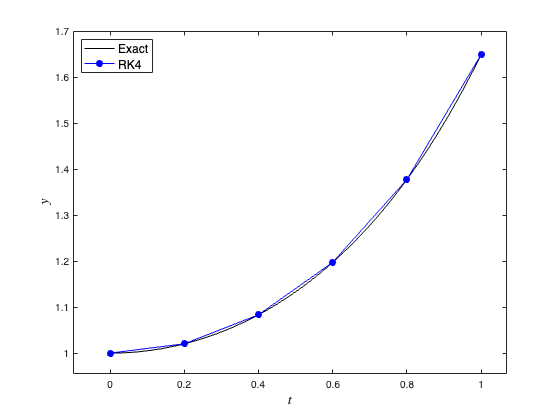

% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=1)
hold on
plot(t, y, 'b-o', LineWidth=1, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'RK4', Location='northwest', FontSize=12)

#### Comparing errors for different methods

% Calculate solution for decreasing step lengths
hvals = [0.2, 0.1, 0.05, 0.025];
E_euler = [];
E_heun = [];
E_rk4 = [];
for h = hvals
    [t, y_euler] = solveIVP(f, tspan, y0, h, @euler);
    [t, y_heun] = solveIVP(f, tspan, y0, h, @heun);
    [t, y_rk4] = solveIVP(f, tspan, y0, h, @rk4);
    E_euler = [E_euler, abs(exact(t(end)) - y_euler(end))];
    E_heun = [E_heun, abs(exact(t(end)) - y_heun(end))];
    E_rk4 = [E_rk4, abs(exact(t(end)) - y_rk4(end))];
end

% Output table of errors (for loop is used to group print statements)
for i = 1 : 1
    fprintf('|   t   |   Euler  |   Heun   |   RK4    |')
    fprintf('|:-----:|:--------:|:--------:|:--------:|');
    for n = 1 : length(hvals)
        fprintf('\n| %1.3f | %1.2e | %1.2e | %1.2e |', hvals (n), E_euler(n), E_heun(n), E_rk4(n))
    end
end

|   t   |   Euler  |   Heun   |   RK4    |

|:-----:|:--------:|:--------:|:--------:|


| 0.200 | 1.89e-01 | 3.88e-03 | 4.59e-06 |
| 0.100 | 1.02e-01 | 8.40e-04 | 2.64e-07 |
| 0.050 | 5.28e-02 | 1.92e-04 | 1.55e-08 |
| 0.025 | 2.69e-02 | 4.55e-05 | 9.33e-10 |

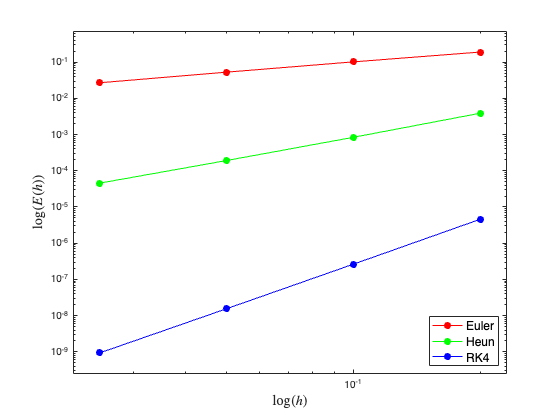


% Plot errors on a loglog scale
loglog(hvals, E_euler, 'ro-', MarkerFaceColor='r', LineWidth=1)
hold on
loglog(hvals, E_heun, 'go-', MarkerFaceColor='g', LineWidth=1)
loglog(hvals, E_rk4, 'bo-', MarkerFaceColor='b', LineWidth=1)
hold off
axis padded
xlabel('$\log(h)$', FontSize=14, Interpreter='latex')
ylabel('$\log(E(h))$', FontSize=14, Interpreter='latex')
legend('Euler', 'Heun', 'RK4', Location='southeast', FontSize=12)

#### Example 2.8

The Bogacki-Shampine 2(3) embedded Runge-Kutta method has the Butcher tableau


$$    \begin{array}{c|cccc}
        0 & \\
        1/2 & 1/2 \\
        3/4 & 0 & 3/4 \\
        1 & 2/9 & 1/3 & 4/9 \\ \hline
        & 2/9 & 1/3 & 4/9 & 0 \\
        & 7/24 & 1/4 & 1/3 & 1/8
    \end{array}$$


where the first row of $b$ values gives a third-order method and the second row gives a second-order method. Compute the first step of the Bogacki-Shampine method for the following initial value problem using an initial step length of $h_0 = 0.1$ and an accuracy tolerance of $tol = 10^{-4}$


$$y' = -21 y + e^{-t}, \qquad t \in [0, 1], \qquad y(0) = 0.$$


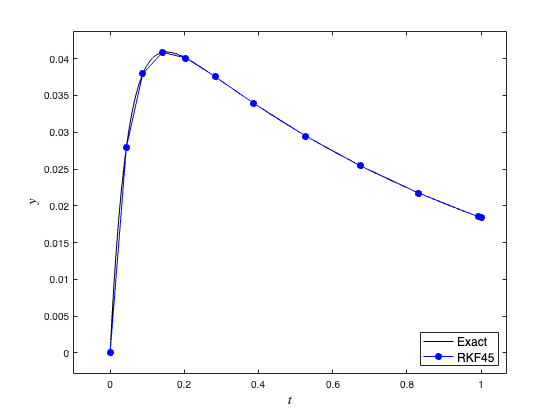

% Define ODE function and exact solution
f = @(t, y) -21 * y + exp(-t);
exact = @(t) 1/20 * exp(-21 * t) .* (exp(20 * t) - 1);

% Define IVP parameters
tspan = [0, 1];     % boundaries of the t domain
y0 = 0;             % initial value of the solution
h0 = 0.1;           % step length
tol = 1e-4;         % accuracy tolerance

% Calculate the solution to the IVP
[t, y] = solveIVP_SSC(f, tspan, y0, h0, tol, @rkf45);

% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=1)
hold on
plot(t, y, 'b-o', LineWidth=1, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'RKF45', Location='southeast', FontSize=12)

## Functions

#### Single step solver

function [t, y] = solveIVP(f, tspan, y0, h, solver)

% Define t and y arrays
t = (tspan(1) : h : tspan(2));
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Loop through the steps and calculate single step solver solution
for n = 1 : length(t) - 1
    y(n+1,:) = solver(f, t(n), y(n,:), h);
end

end

#### Euler method

function ynew = euler(f, t, y, h)

ynew = y + h * f(t, y);

end

#### RK4 method

function ynew = rk4(f, t, y, h)

k1 = f(t, y);
k2 = f(t + 0.5 * h, y + 0.5 * h * k1);
k3 = f(t + 0.5 * h, y + 0.5 * h * k2);
k4 = f(t + h, y + h * k3);
ynew = y + h / 6 * (k1 + 2 * k2 + 2 * k3 + k4);

end

#### Heun's method

function ynew = heun(f, t, y, h)

k1 = f(t, y);
k2 = f(t + h, y + h * k1);
ynew = y + h / 2 * (k1 + k2);

end

#### IVP solver using adaptive step size control

function [t, y] = solveIVP_SSC(f, tspan, y0, h, tol, solver)

% Define t and y arrays
t = zeros(10000);
y = zeros(10000, length(y0));
t(1) = tspan(1);
y(1,:) = y0;

% Loop through the steps
n = 1;
while t(n) < tspan(2)
    
    % Calculate order p and p+1 solutions
    [yp1, yp, order] = solver(f, t(n), y(n,:), h);
    delta = max(abs(yp1 - yp));

    % Determine whether the step was successful or not
    if delta < tol
        y(n+1,:) = yp1;
        t(n+1) = t(n) + h;
        n = n + 1;
    end

    % Calculate new value of h (making sure not to exceed tmax)
    h = h * max(0.5, min(2, 0.9 * (tol / delta) ^ (1 / (order + 1))));
    h = min(h, tspan(2) - t(n));

end

% Remove unused entries from t and y
t(n+1:end) = [];
y(n+1:end,:) = [];

end

#### Fehlbergs 4(5) embedded Runge-Kutta method

function [y5, y4, order] = rkf45(f, t, y, h)

k1 = f(t, y);
k2 = f(t + 1/4 * h, y + 1/4 * h * k1);
k3 = f(t + 3/8 * h, y + h * (3/32 * k1 + 9/32 * k2));
k4 = f(t + 12/13 * h, y + h * (1932/2197 * k1 - 7200/2197 * k2 + 7296/2197 * k3));
k5 = f(t + h, y + h * (439/216 * k1 - 8 * k2 + 3680/513 * k3 - 845/4104 * k4));
k6 = f(t + 1/2 * h, y + h * (-8/27 * k1 + 2 * k2 - 3544/2565 * k3 + 1859/4104 * k4 - 11/40 * k5));
y5 = y + h * (16/135 * k1 + 6656/12825 * k3 + 28561/56430 * k4 - 9/50 * k5 + 2/55 * k6);
y4 = y + h * (25/216 * k1 + 1408/2565 * k3 + 2197/4104 * k4 - 1/5 * k5);
order = 4;

end

#### Bogacki-Shampine 2(3) embedded Runge-Kutta method

function [y3, y2, order] = rkbs23(f, t, y, h)

k1 = f(t, y);
k2 = f(t + 1/2 * h, y + 1/2 * h * k1);
k3 = f(t + 3/4 * h, y + 3/4 * h * k2);
k4 = f(t + h, y + h * (2/9 * k1 + 1/3 * k2 + 4/9 * k3));
y3 = y + h * (2/9 * k1 + 1/3 * k2 + 4/9 * k3);
y2 = y + h * (7/24 * k1 + 1/4 * k2 + 1/3 * k3 + 1/8 * k4);
order = 2;

end